# 球板模型图

- [Zhihu: https://www.zhihu.com/people/1105936347](https://www.zhihu.com/people/1105936347)

- [Github: https://github.com/AFei19911012](https://github.com/AFei19911012)

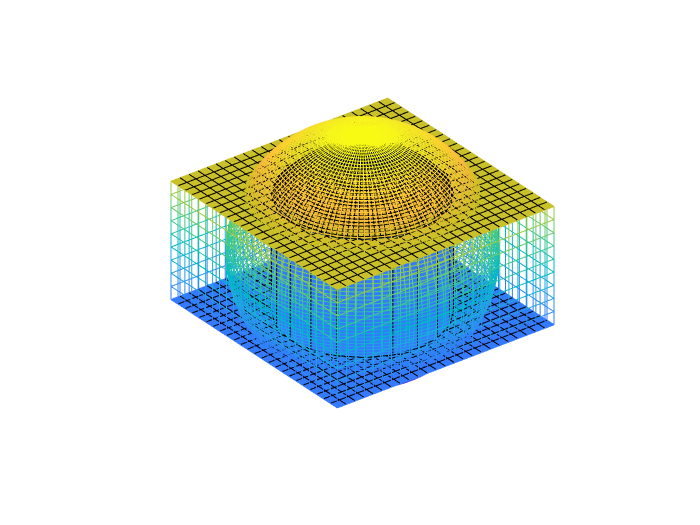

clear; clc;
% 生成球面数据
[x1, y1, z1] = sphere(101);         
z0 = z1;
% 半径 0.8 之外的不显示
z1(x1.^2 + y1.^2 >= 0.8^2) = nan;   
x0 = linspace(-1.2, 1.2, 25);
z = linspace(-0.6, 0.6, 10);
[x, z] = meshgrid(x0, z);
y0 = zeros(size(x));
[x2, y2] = meshgrid(x0);
% 生成圆柱数据
[x3, y3, z3] = cylinder(0.8);       
s = zeros(size(x2));
% 绘制两个球冠
surf(x1, y1, z1);
hold on
% 绘制上下两个面
surf(x2, y2, s-0.6);              
surf(x2, y2, s+0.6);
% 绘制圆柱面
surf(x3, y3, 1.2 * (z3 - 0.5));
% 绘制四个侧面
mesh(x, y0-1.2, z);
mesh(x, y0+1.2, z);
mesh(y0+1.2, x, z);
mesh(y0-1.2, x, z);
% 绘制两个大的球冠
mesh(1.2*x1, 1.2*y1, 1.2*z0);
% 镂空
hidden off
hold off
axis equal
axis square
axis off